function [X, Y] = nodes(a, b, segments_n, f)
n = 1 + segments_n * 3;
X = linspace(a, b, n);
Y = f(X);
end

function res = export_nodes(filename, X, Y)
file = fopen(filename, "w");
fwrite(file, numel(X), "int");
fwrite(file, X, "double");
fwrite(file, Y, "double");
fclose(file);
end

a = -0.7;
b = 1.6;

f = @(x) x.^5 - 3.2*x.^3 + 9.5*x.^2 - 7*x - 7.5;
If = @(x) x.^6/6 - 3.2/4*x.^4 + 9.5/3*x.^3 - 7/2*x.^2 - 7.5*x;

If(b) - If(a)

ans = -12.7124

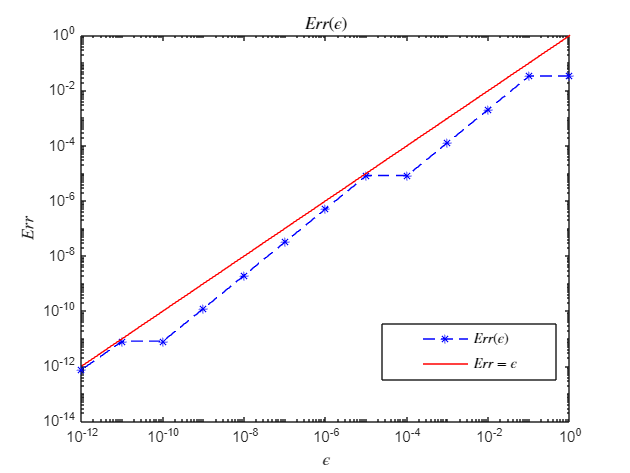

T1 = readtable("err_eps.csv");
eps = T1{1:end, 1};
Err = T1{1:end, 2};

figure
loglog(eps, Err, "b*--");
hold on
loglog(eps, eps, "r-");
legend("$Err(\epsilon)$", "$Err = \epsilon$", Interpreter="latex", Position=[0.6073 0.1990 0.2762, 0.1172])
xlabel("$\epsilon$", Interpreter="latex");
ylabel("$Err$", Interpreter="latex");
title("$Err(\epsilon)$", Interpreter="latex");

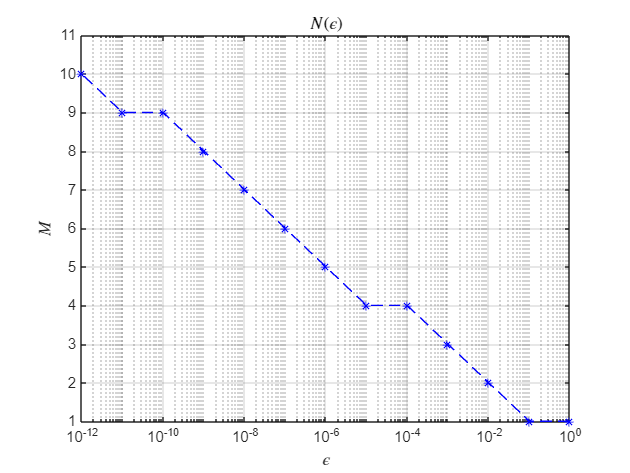

T2 = readtable("n_eps.csv");
M = T2{1:end, 2};

figure
semilogx(eps, M, "b*--");
grid on
ylim([1 11])
xlabel("$\epsilon$", Interpreter="latex");
ylabel("$M$", Interpreter="latex");
title("$N(\epsilon)$", Interpreter="latex");

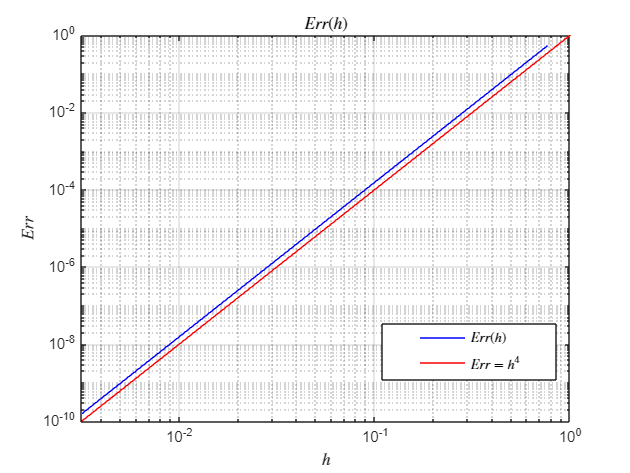

T3 = readtable("Err_h.csv");
Err1 = T3{1:end, 2};
h = T3{1:end, 1};

domain = 10.^linspace(-2.5, 1, 100);
target = domain.^4;

figure
loglog(h, Err1, "b-");
hold on;
loglog(domain, target, "r-");
grid on
xlabel("$h$", Interpreter="latex");
ylabel("$Err$", Interpreter="latex");
title("$Err(h)$", Interpreter="latex");
legend("$Err(h)$", "$Err = h^4$", Interpreter="latex", Position=[0.6073 0.1990 0.2762, 0.1172])
xlim([10^-2.5, 1])
ylim([10^-10 1])